# Driver test program to check clothoid computation 

%=========================================================================%
%                                                                         %
%  Autors: Enrico Bertolazzi                                              %
%          Department of Industrial Engineering                           %
%          University of Trento                                           %
%          enrico.bertolazzi@unitn.it                                     %
%                                                                         %
%=========================================================================%

## Data XY for the clothoid

tol = 1e-10;

XY = 1.0e+02 * [...
  -4.839456676074770,  -0.687801210926846; ...
  -4.854012555484660,  -0.702211958309636; ...
  -4.863436554332729,  -0.718581445114687; ...
  -4.869128276407719,  -0.735790389403701; ...
  -4.875846374598332,  -0.791894321963191; ...
  %-4.879112116773613,  -0.797350812163204; ...
  -4.879112116773613,  -0.797350812163204; ...
  -4.891242016281467,  -0.801967842094600; ...
  -4.899266411340795,  -0.791194771928713; ...
];
X = XY(:,1); Y = XY(:,2);

## Close all windows

close all;

## Initialize G2 clothoid spline object

S  = ClothoidSplineG2();
S.ipopt(true); % if you have ipopt and not Optimization toolbox
%S.ipopt_check(true);

## Compute various G2 clothoid spline with different target

SPL = cell(8,1);

SPL{1} = S.buildP1( X, Y, -pi, -pi ); %3.141592653589793, 7.647610983392527 );


                                        First-Order                    Norm of 
 Iteration  Func-count    Residual       optimality      Lambda           step
     0           1         3.30494            8.97         0.01
     1           2       0.0109938           0.458        0.001        1.29884
     2           3     1.84907e-08          0.0008       0.0001      0.0246351
     3           4      2.0455e-18        3.64e-09        1e-05    2.49864e-05
     4           5     7.57087e-28        2.13e-13        1e-06    1.30514e-09

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

SPL{3} = S.buildP3( X, Y, SPL{1}.thetaBegin(), SPL{1}.kappaBegin() );

SPL{1} = S.buildP1( X, Y, -pi/2, 0 ); %3.141592653589793, 7.647610983392527 );


                                        First-Order                    Norm of 
 Iteration  Func-count    Residual       optimality      Lambda           step
     0           1         7.34319            8.97         0.01
     1           2        0.293412            2.53        0.001         2.3882
     2           3     3.72327e-05          0.0283       0.0001       0.125367
     3           4     7.27323e-13        3.85e-06        1e-05     0.00143369
     4           5     4.60338e-25        2.07e-12        1e-06    2.07016e-07

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

SPL{2} = S.buildP2( X, Y );


                                        First-Order                    Norm of 
 Iteration  Func-count    Residual       optimality      Lambda           step
     0           1         5.91617            8.97         0.01
     1           2       0.0768213           0.698        0.001        1.38639
     2           3     3.82438e-06         0.00669       0.0001       0.100721
     3           4     6.17505e-16        9.88e-08        1e-05    0.000569549
     4           5     2.96418e-27        7.67e-14        1e-06    9.67624e-09

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

SPL{4} = S.buildP4( X, Y );


******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         For more information visit https://github.com/coin-or/Ipopt
******************************************************************************

This is Ipopt version 3.13.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:       18
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:        0

Total number of variables............................:        8
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        8
                     variables with only upper bounds:        0
Total number of equal

SPL{5} = S.buildP5( X, Y );

This is Ipopt version 3.13.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:       18
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:        0

Total number of variables............................:        8
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        8
                     variables with only upper bounds:        0
Total number of equality constraints.................:        6
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  

SPL{6} = S.buildP6( X, Y );

This is Ipopt version 3.13.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:       18
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:        0

Total number of variables............................:        8
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        8
                     variables with only upper bounds:        0
Total number of equality constraints.................:        6
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  

SPL{7} = S.buildP7( X, Y );

This is Ipopt version 3.13.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:       18
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:        0

Total number of variables............................:        8
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        8
                     variables with only upper bounds:        0
Total number of equality constraints.................:        6
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  

SPL{8} = S.buildP8( X, Y );

This is Ipopt version 3.13.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:       18
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:        0

Total number of variables............................:        8
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        8
                     variables with only upper bounds:        0
Total number of equality constraints.................:        6
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  

SPL{9} = S.buildP9( X, Y );

This is Ipopt version 3.13.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:       18
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:        0

Total number of variables............................:        8
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        8
                     variables with only upper bounds:        0
Total number of equality constraints.................:        6
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  

## Plot results

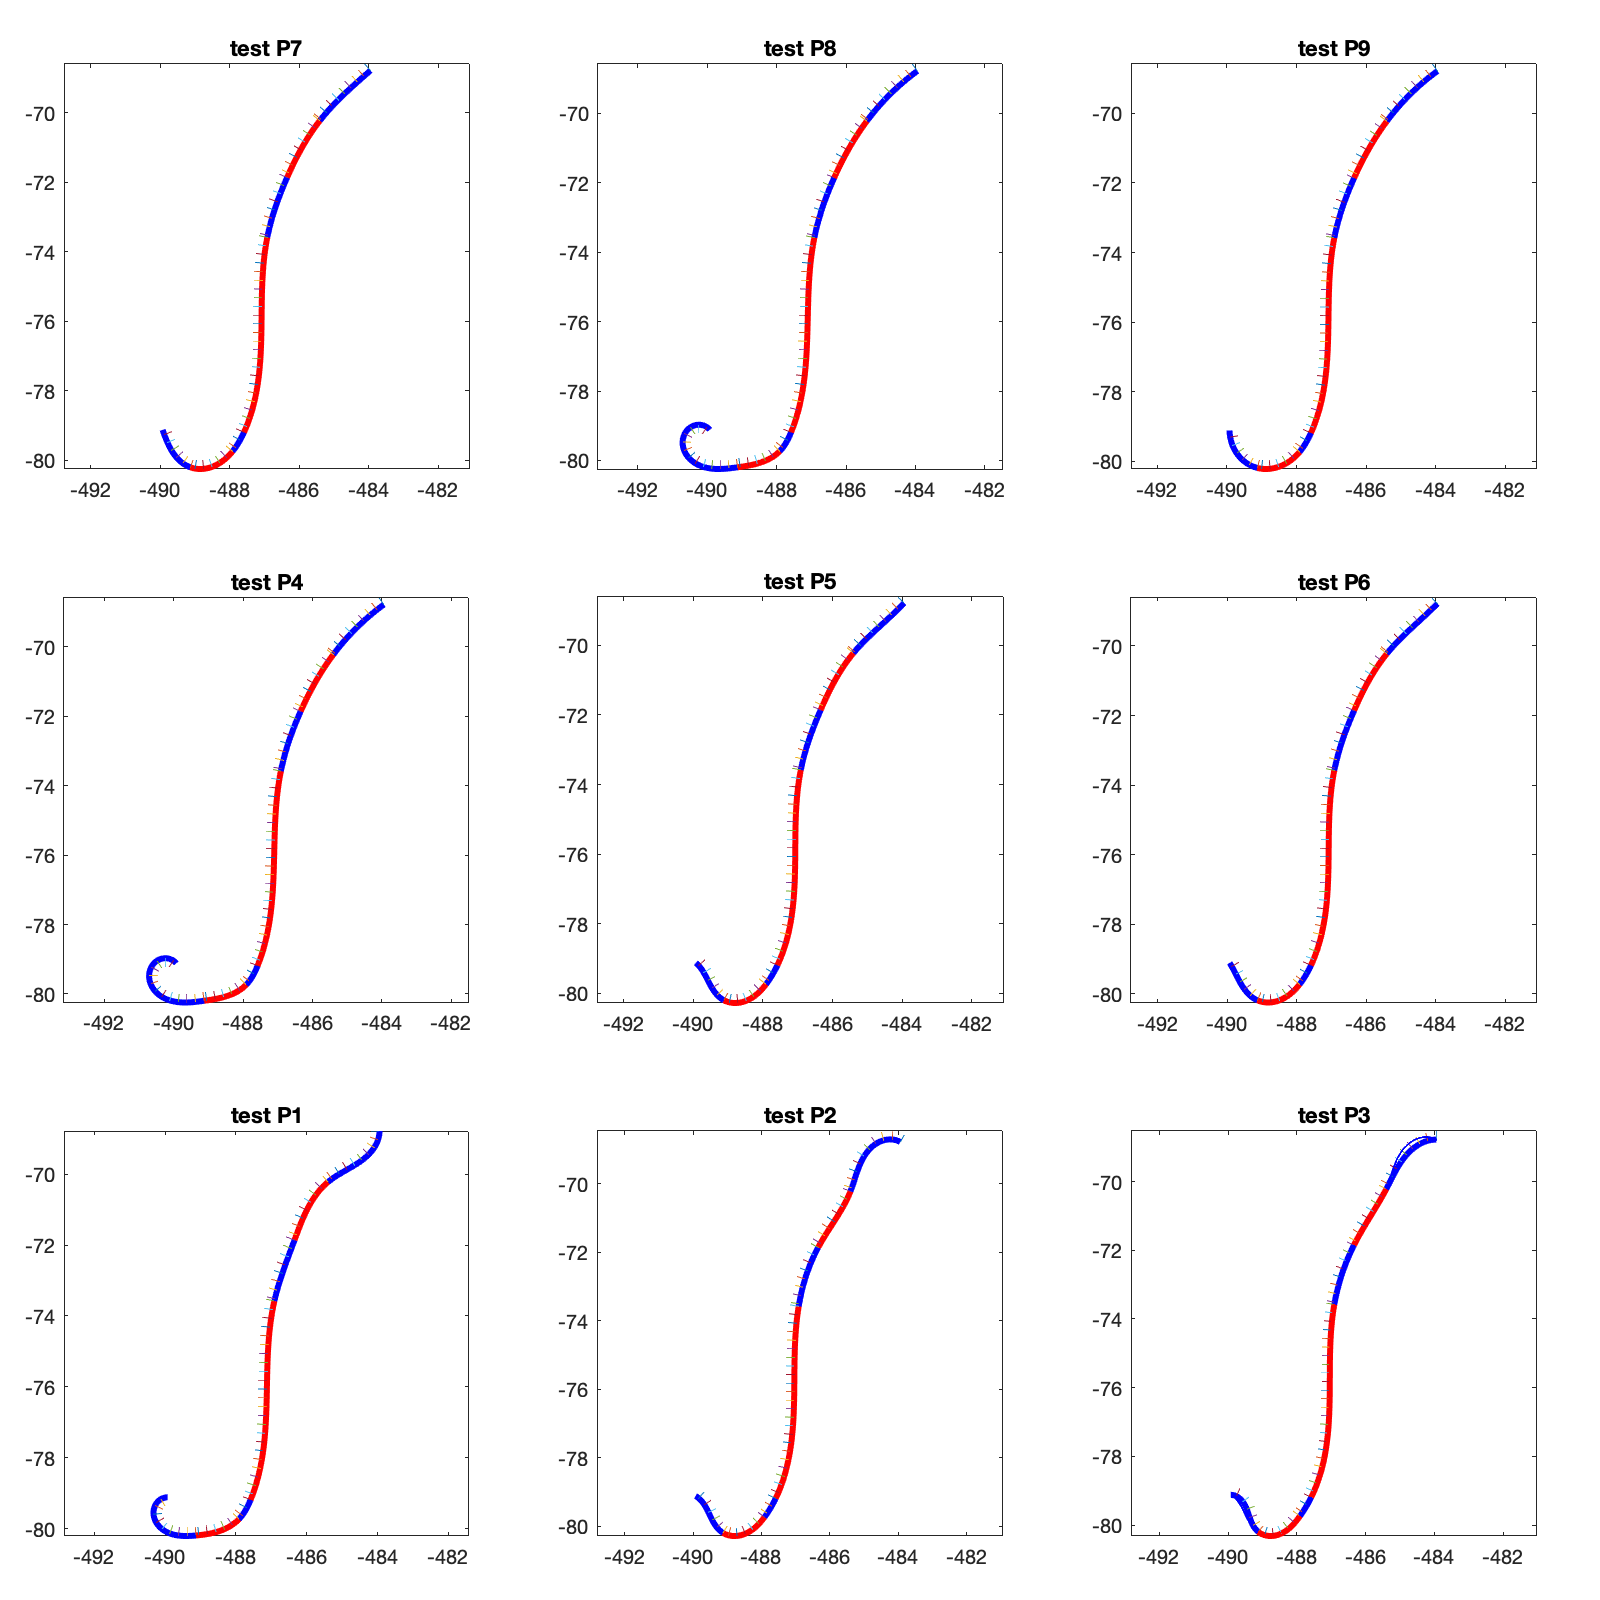

plot target N.1


plot target N.2


plot target N.3


plot target N.4


plot target N.5


plot target N.6


plot target N.7


plot target N.8


plot target N.9


aa = 0.04;
bb = 1/3-2*aa;

figure('Position',[ 1 1 800 800]);

for k=1:9
  fprintf('plot target N.%d\n',k);
  switch(k)
  case 1; subplot('Position',[aa     aa     bb bb]);
  case 2; subplot('Position',[aa+1/3 aa     bb bb]);
  case 3; subplot('Position',[aa+2/3 aa     bb bb]);
  case 4; subplot('Position',[aa     aa+1/3 bb bb]);
  case 5; subplot('Position',[aa+1/3 aa+1/3 bb bb]);
  case 6; subplot('Position',[aa+2/3 aa+1/3 bb bb]);
  case 7; subplot('Position',[aa     aa+2/3 bb bb]);
  case 8; subplot('Position',[aa+1/3 aa+2/3 bb bb]);
  case 9; subplot('Position',[aa+2/3 aa+2/3 bb bb]);
  end
  
  % subplot(3,3,k);
  SPL{k}.plot();
  SPL{k}.plotNormal(0.25,0.25);

  if k == 3
    hold on
    SPL{2}.plot(1000,{'Color','red','LineWidth',1},{'Color','blue','LineWidth',1});
  end

  title(sprintf('test P%d',k));

  axis equal;
end

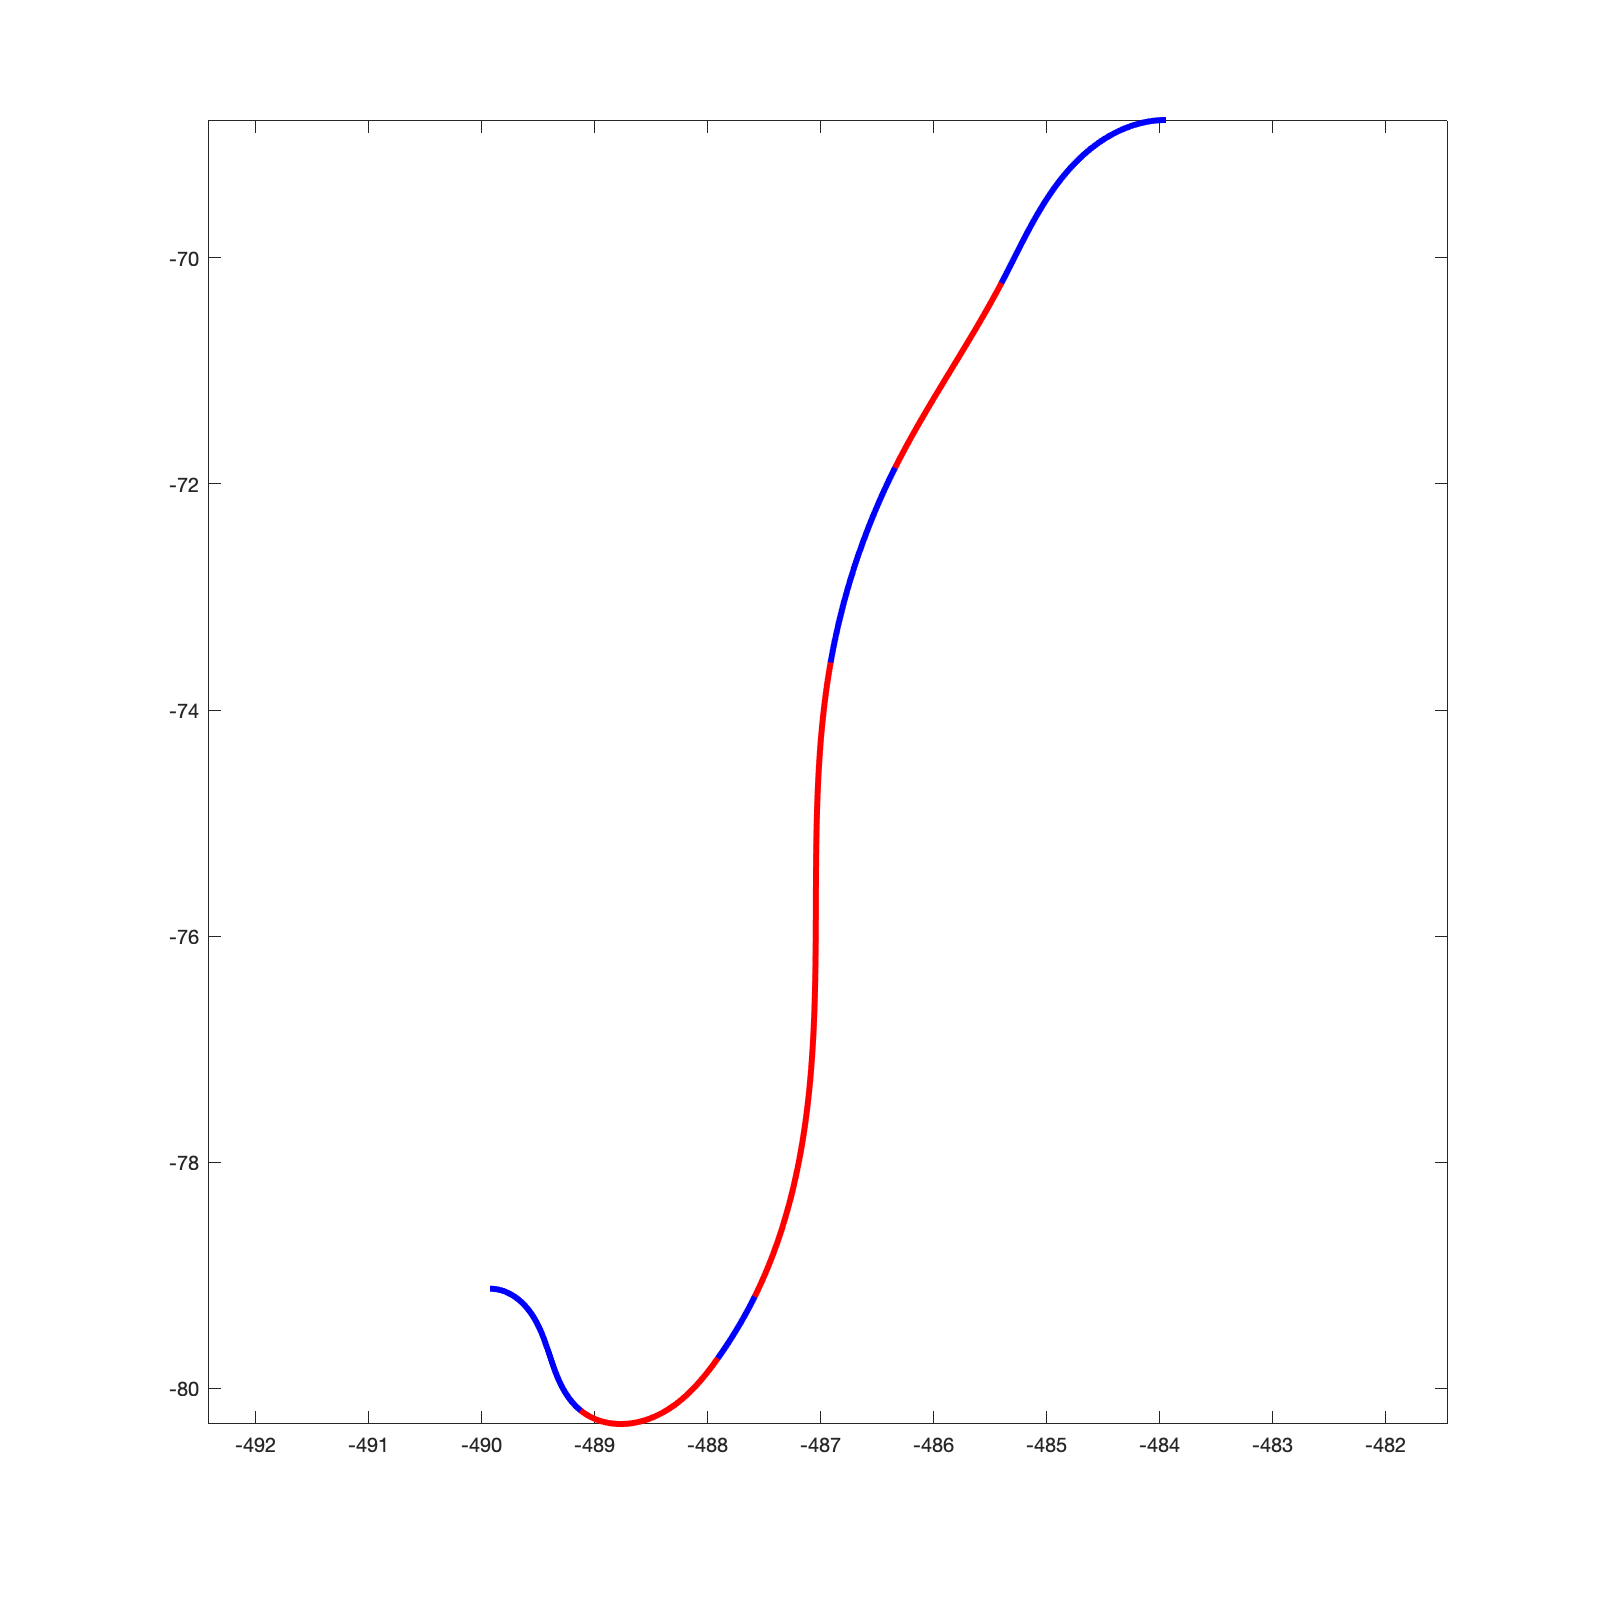

SPL{3}.save('G2_test.txt');
SS  = ClothoidList();
SS.load('G2_test.txt');
subplot(1,1,1);
SS.plot();
axis equal;

SS.info()

ClothoidList
x0     = -483.946     x1     = -485.401    
y0     = -68.7801     y1     = -70.2212    
theta0 = -3.14159     theta1 = -2.05484    
kappa0 = 1.14599      kappa1 = -0.141570   
dk     = -0.595007    L      = 2.16394     

x0     = -485.401     x1     = -486.344    
y0     = -70.2212     y1     = -71.8581    
theta0 = -2.05484     theta1 = -2.03606    
kappa0 = -0.141570    kappa1 = 0.161449    
dk     = 0.160387     L      = 1.88930     

x0     = -486.344     x1     = -486.913    
y0     = -71.8581     y1     = -73.5790    
theta0 = -2.03606     theta1 = -1.74535    
kappa0 = 0.161449     kappa1 = 0.158192    
dk     = -0.00179047  L      = 1.81898     

x0     = -486.913     x1     = -487.585    
y0     = -73.5790     y1     = -79.1894    
theta0 = -1.74535     theta1 = -2.03044    
kappa0 = 0.158192     kappa1 = -0.258366   
dk     = -0.0731856   L      = 5.69180     

x0     = -487.585     x1     = -487.911    
y0     = -79.1894     y1     = -79.7351    
theta0 = -2.030